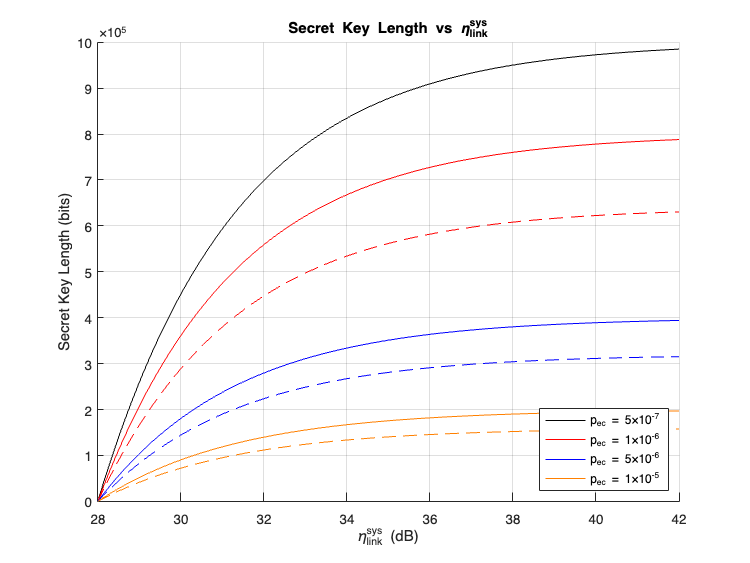

% Valores de η_link^sys (dB)
x = linspace(28, 42, 100); % Rango del eje x

% Curvas simuladas crecientes
% Cuanto menor es p_ec, mayor es la curva

% p_ec = 5e-7 (negro)
y1_solid = 1e6 * (1 - exp(-0.3 * (x - 28)));
y1_dashed = y1_solid * 0.8;

% p_ec = 1e-6 (rojo)
y2_solid = 8e5 * (1 - exp(-0.3 * (x - 28)));
y2_dashed = y2_solid * 0.8;

% p_ec = 5e-6 (azul)
y3_solid = 4e5 * (1 - exp(-0.3 * (x - 28)));
y3_dashed = y3_solid * 0.8;

% p_ec = 1e-5 (naranja)
y4_solid = 2e5 * (1 - exp(-0.3 * (x - 28)));
y4_dashed = y4_solid * 0.8;

% Crear la gráfica
figure;
hold on;
plot(x, y1_solid, 'k-', 'DisplayName', 'p_{ec} = 5×10^{-7}');
plot(x, y1_dashed, 'k--', 'HandleVisibility','off');

plot(x, y2_solid, 'r-', 'DisplayName', 'p_{ec} = 1×10^{-6}');
plot(x, y2_dashed, 'r--', 'HandleVisibility','off');

plot(x, y3_solid, 'b-', 'DisplayName', 'p_{ec} = 5×10^{-6}');
plot(x, y3_dashed, 'b--', 'HandleVisibility','off');

plot(x, y4_solid, '-', 'Color', [1 0.5 0], 'DisplayName', 'p_{ec} = 1×10^{-5}');
plot(x, y4_dashed, '--', 'Color', [1 0.5 0], 'HandleVisibility','off');

xlabel('\eta_{link}^{sys} (dB)');
ylabel('Secret Key Length (bits)');
title('Secret Key Length vs \eta_{link}^{sys}');
legend('Location', 'southeast');
grid on;
hold off;

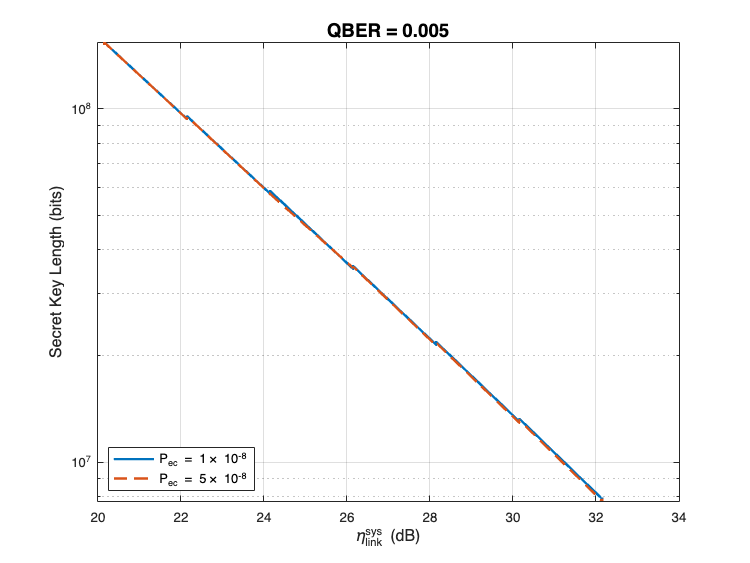

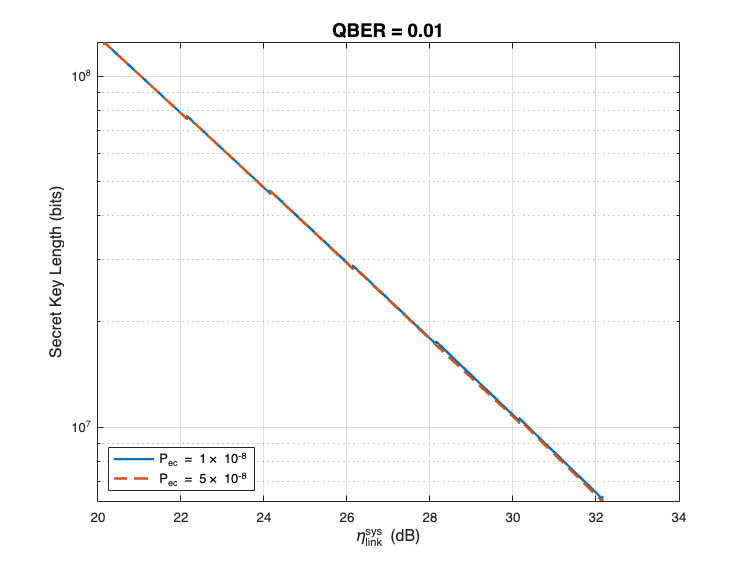

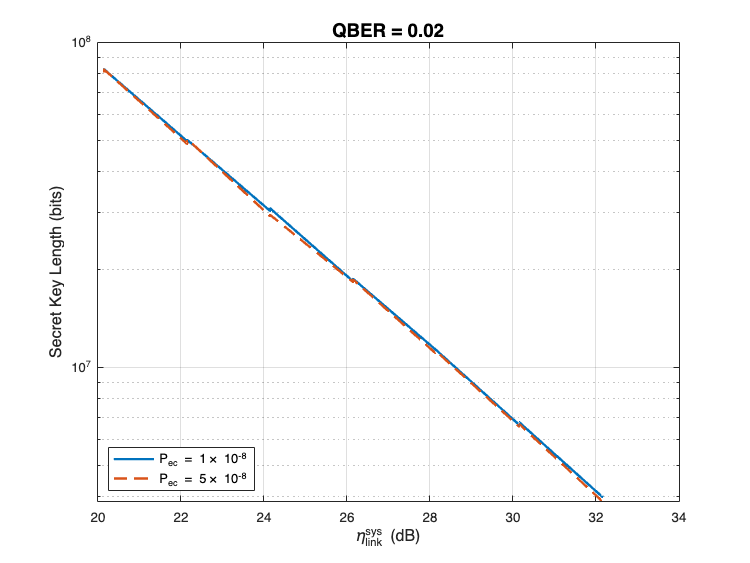

% Ruta donde están los CSV
folder = '/Users/minaal/Documents/TFG/BIJAY SOFTWARE SIMULATOR QKD/SatQuMA-main/SatQuMA-main/out/Datos/Tanda3-1405';
files = dir(fullfile(folder, '*.csv'));

% QBERI a representar
qber_values = {'0.005', '0.01', '0.02'};

% Paleta de colores
colors = lines(10);

% Estilos de línea alternos
linestyles = {'-', '--', ':', '-.'};

for q = 1:length(qber_values)
    figure;
    hold on; grid on;
    set(gca, 'YScale', 'log');
    xlabel('\eta_{link}^{sys} (dB)', 'FontSize', 12);
    ylabel('Secret Key Length (bits)', 'FontSize', 12);
    title(['QBER = ', qber_values{q}], 'FontSize', 14);

    count = 0;
    legend_entries = {};

    for k = 1:length(files)
        filename = files(k).name;

        if contains(filename, ['_', qber_values{q}, '.csv'])
            count = count + 1;
            fullpath = fullfile(folder, filename);
            data = readtable(fullpath);

            % Leer valores
            x = data.SysLoss_dB_;
            y = data.SKL_b_;

            % Ordenar por SysLoss
            [x_sorted, idx] = sort(x);
            y_sorted = y(idx);

            % Filtrar valores válidos (>0 y no NaN)
            valid_idx = y_sorted > 0 & ~isnan(y_sorted);
            x_valid = x_sorted(valid_idx);
            y_valid = y_sorted(valid_idx);

            % Extraer Pec del nombre
            underscore_idx = strfind(filename, '_');
            pec_str = filename(1:underscore_idx(1)-1);
            legend_entries{count} = ['P_{ec} = ', strrep(pec_str, 'e', '\times 10^{'), '}'];

            % Seleccionar color y estilo
            color = colors(mod(count-1, size(colors,1)) + 1, :);
            linestyle = linestyles{mod(count-1, length(linestyles)) + 1};

            % Dibujar curva
            plot(x_valid, y_valid, 'LineWidth', 1.8, 'Color', color, 'LineStyle', linestyle);
        end
    end

    legend(legend_entries, 'Location', 'southwest', 'FontSize', 10);
    box on;

    % Guardar imagen
    print(['grafica_QBER_' qber_values{q}], '-dpng', '-r300');
end

        valid_idx = y_sorted > 0 & ~isnan(y_sorted);

Error using readtable
Unable to find or open '/Users/minaal/Documents/TFG/BIJAY SOFTWARE SIMULATOR QKD/SatQuMA-main/SatQuMA-main/out/Datos/Tanda3-1405/'. Check the path and filename or file permissions.

Unsupported use of the '=' operator. To compare values for equality, use '=='. To specify name-value arguments, check that name is a valid identifier with no surrounding quotes.